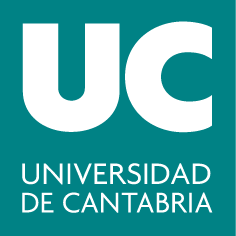

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **4. Límites y derivadas**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Límite

El comando` limit `permite calcular directamente el límite de una función, ya sea esta anónima o simbólica.

**Ejemplo:** Calculamos los siguientes límites:

a) $$\lim\limits_{x\to\infty} \frac{x^4 - x^3 + 5}{3x^4 + x^2 - 4x}$$

clearvars
syms x real                                  % defino x como variable simbolica real
f = @(x)  (x^4 - x^3 + 5) / (3*x^4 + x^2 - 4*x);  % funcion anonima
L = limit(f, x, inf)

Para pasar a formato decimal podemos recurrir al comando `double`:

Lnum = double(L)

b) $$\lim\limits_{x\to0} \frac{(1-\cos x)^2}{2sen^4x - sen^5x}$$

Podemos definir $f(x)$ como una función anónima

f = @(x)  (1-cos(x))^2 / (2*sin(x)^4 - sin(x)^5);
L = limit(f, x, 0)

#### Límites laterales

Los límites laterales:

- por la derecha: $$\lim\limits_{x \rightarrow a+} f(x) = \lim\limits_{h \rightarrow 0} f(a+h) $, $h>0$$

- por la izquierda: $$\lim\limits_{x \rightarrow a-} f(x) = \lim\limits_{h \rightarrow 0} f(a-h) $, $h>0$$

Recuerda que **el límite de una función en un punto existe si, y sólo si, existen los dos límites laterales en dicho punto y ambos coinciden:**


$$$$\lim\limits_{x \rightarrow a} f(x) = \ell  \Leftrightarrow\lim\limits_{x \rightarrow a+} f(x) =  \lim\limits_{x \rightarrow a-} f(x) = \ell$$$$


 **Ejemplo:** $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$

clearvars
syms x real  
f = sin(abs(x)) / x;

1. Calculamos límite por la derecha:

L_der = limit(f, x, 0, 'right') 

2. Calculamos límite por la izquierda:

L_izq = limit(f, x, 0, 'left') 

Ambos existen, pero no coinciden. Por lo tanto, el límite $$\lim\limits_{x\to0} \frac{sen\mid{x}\mid}{x}$$ no existe:

L = limit(f, x, 0) 

#### Continuidad

A partir del cálculo de límites podemos estudiar la continuidad de una función. Para ello será conveniente conocer el comando `solve`, que permite resolver sistemas de ecuaciones. En el caso de una sola ecuación con una única incógnita, su sintaxis es la siguiente:

**Ejemplo: **Resolvemos la ecuación $x^2 - 5x-6 = 0$ 

syms x real
raices1 = solve(x^2 - 5*x - 6 == 0)   % raices ecuacion segundo grado --> x = {-1,6}
raices2 = solve(x^2 - 5*x - 6)        % equivalente a la orden anterior

El comando `solve` está diseñado para trabajar con expresiones simbólicas. Por tanto, en el caso de funciones anónimas, habría que convertirlas antes al tipo simbólico con ayuda del comando `sym`:

f = @(x)  4*x^2 - x;
% raices = solve(f)        % no permitido
raices = solve(sym(f))   % permitido --> x = {0, 1/4}

El resultado devuelto por` solve `también es una expresión simbólica:

R = double(raices)  % paso a decimal

**Ejemplo**: Estudia la continuidad de la función $$f(x) = \frac{x}{x^2-x}$$

1. Definimos la función: 

clearvars
syms x real
f(x) =  x / (x^2 - x);

2. Hallamos los puntos de discontinuidad: $f(x)$ no esta definida en los puntos en los que el denominador se anule:

puntos_discontinuidad = double(solve(x^2 - x)) 

3. Para estudiar si la discontinuidad es evitable o no, calculamos los límites:

- en $x = 0:$

L1 = limit(f, x, puntos_discontinuidad(1)) 

El límite existe, por lo tanto es una discontinuidad evitable.

- en $x = 1$:

L2 = limit(f, x, puntos_discontinuidad(2))  

El límite no existe, entonces en $x = 1$ la función tiene una discontinuidad inevitable.

4. Representamos gráficamente la función y marcamos el punto de discontinuidad evitable:

fplot(f,'b-')
grid on
hold on
plot(puntos_discontinuidad(1), L1,'ro')
hold off

En el punto de discontinuidad inevitable, la función presenta una asíntota vertical.

### Derivación

#### Definición

La derivada de una función $$f(x)$$ en punto $$a$ $viene dada por

			
$$	$$f'(a) = \lim\limits_{\Delta x \rightarrow 0} \frac{f(a+\Delta x)-f(a)}{\Delta x} $$$$


Así, podemos calcular la derivada por la definición:

#### Comando `diff`

Pero también podemos utilizar la función `diff`. Al igual que` limit, diff `acepta tanto funciones anónimas como simbólicas:

**Ejemplo**: Calculamos $ $f'(x)$ $siendo $$f(x) ={x^4 - x^3 + 5}$$ usando ambos comandos:

1. Definimos la función:

clearvars
syms x real
f(x) = (x^4 - x^3 + 5)   % funcion simbólica

2. Calculamos la derivada por la definición:

syms dx
df1(x) = limit ( (f(x+dx) - f(x))/dx, dx, 0)

3. Calculamos la derivada utilizando el comando `diff`: 

df2(x) = diff(f) 

Ambas opciones dan mismo resultado.

#### Derivadas de orden superior

Las **derivadas de orden superior** se refieren a la derivación repetida de una función. Para calcular la derivada de orden superior:

Por ejemplo, para la segunda derivada:

d2f(x) = diff(f, x, 2)  

**Ejercicio**: Calcula las derivadas de la función  $f(x) = sen(x)$ hasta el cuarto orden. Comprueba que $f^{(4)}(x) = f(x)$.

% escribe aquí el código:




Solución:

clearvars
syms x real
f(x) = sin(x);
df(x) = diff(f)
d2f(x) = diff(f, x, 2) % que es equivalente a d2f(x) = diff(df)
d3f(x) = diff(f,x,3)
d4f(x) = diff(f,x,4)

**Ejemplo: **Siendo $$f(x) = \frac{sen(x)^4}{x^2 + e^x}$$, calcula $$f'(\pi)$$ y$ $f''(-4)$$:

clearvars
syms x real

f(x) =  sin(x)^4 / (x^2 + exp(x));  % funcion simbólica
f_prima(x) = diff(f, x, 1);  % derivada de orden 1
f_prima2(x) = diff(f, x, 2);  % derivada de orden 2

f_prima_pi = double(f_prima(pi))  % f'(x=pi)
f_prima2_4 = double(f_prima2(-4))  % f''(x=-4)

#### Recta tangente

Con lo que hemos visto ahora podríamos calcular (y dibujar) las rectas tangentes y normales a una curva dada.

- Recta tangente: $$$y-f(a) = f'(a)(x-a)$$$

- Recta normal (perpendicular a la recta tangente):$ $$y-f(a) =-\frac{1}{f'(a)}(x-a)$$$

**Ejemplo:** Calculamos las tangentes a $$f(x) = x^3 - 3x$$ que sean paralelas a la recta $ $y = 6x + 10$$. Representa en una misma figura$ $f(x)$$ (en rojo) y las tangentes halladas (con línea discontinua) en el dominio $$[-5, 5]$$. Pon un título y una leyenda adecuada. 

clearvars
syms x real
f(x) = x^3 - 3*x;  

Calculamos la primera derivada:

df(x) = diff(f, x)  % derivada de orden 1

Para encontrar una recta tangente a $f(x)$que sea paralela a la recta  $ $y = 6x + 10$$,  debemos hallar el punto en el cual la derivada  $f'(x)$  es igual a 6, ya que la pendiente de la tangente debe coincidir con la pendiente de la recta dada para que sean paralelas.

a = double(solve(df == 6))  

Son dos puntos. Hallamos las rectas tangentes en cada una:

rt1 = df(a(1))*(x-a(1)) + subs(f, a(1))  % eq. RT en x = a(1)
rt2 = df(a(2))*(x-a(2)) + subs(f, a(2))  % eq. RT en x = a(1)
fplot(f,[-5,5],'r');  hold on % dibujo f
fplot(rt1,'k--');  % dibujo recta tangente en x = a(1)
fplot(rt2,'b--');  % dibujo recta tangente en x = a(2)
grid on
legend('f(x)', 'RT1', 'RT2')
xlabel('eje x'), ylabel('eje y')
title('Rectas tangentes')
hold off

### Ejercicios propuestos

1. Utiliza la expresión $ $\frac{f(x+\Delta x)-f(x)}{\Delta x}$$ para calcular un valor aproximado de $$\frac{d}{dx} \left( \frac{\ln(1 + x^2)}{sen^2x} \right)$$ en $$x_0 = 1$$ tomando $$\Delta x = \lbrace 0.1; 0.05; 0.0025 \rbrace$.$

 A continuación, calcula el valor exacto de la derivada usando los comandos `limit` y `diff`. Compara las aproximaciones obtenidas con el valor exacto en términos de error porcentual $$\left( \vert \frac{valor_{aprox} - valor_{exacto}}{valor_{exacto}} \vert \cdot 100 \% \right)$$.

% escribe aquí el código:




Solución:

soluciones(1)

2. Halla el punto $$P$$ donde se cortan las funciones$ $f(x) = \frac{2}{x}$$ y $$g(x) = \sqrt{x^2 - 3}$$. Representa en una misma figura $$f$$ (en rojo) y $$g$ $(en azul) en $$[0,5] \times [0,3]$$. Pon una leyenda que identifique cada curva y un título. Halla la ecuación de la tangente a cada curva en $$P$$, dibuja ambas rectas (en el mismo color que la curva correspondiente pero en línea discontinua) y comprueba que son perpendiculares. 

% escribe aquí el código:





Solución:

soluciones(2)

3. Representa la gráfica de la circunferencia$ $x^2 + y^2 + 2y = 9$$ en color negro y con una línea gruesa. Halla todas las rectas tangentes y normales a la circunferencia en el punto $$x_0 = 2$$ y represéntalas en línea discontinua en el dominio $$[-6,6] \times [-8,8]$$. Pon un título.

% escribe aquí el código:





Solución:

soluciones(3)

### Resumen

**Límite**

- [`limit`](https://es.mathworks.com/help/symbolic/sym.limit.html)**:** Se utiliza para calcular el límite (y los límites laterales) de una función, ya sea anónima o simbólica. 

- [`solve`](https://es.mathworks.com/help/symbolic/sym.solve.html)**:** Se emplea para resolver ecuaciones simbólicas (por ejemplo, para encontrar puntos de discontinuidad en la función).

**Derivación**

- [`diff`](https://es.mathworks.com/help/symbolic/diff.html)**:** Calcula la derivada de una función de manera simbólica. También permite calcular derivadas de orden superior.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms x real
        f(x) = log(1+x^2)/sin(x)^2;

        x0 = 1;
        df(x) = diff(f);
        df_exacto = double(df(x0));
        for dx = [0.1, 0.05, 0.0025]
            df_aprox = double(( f(x0+dx) - f(x0))/dx);

            error = abs( (df_aprox - df_exacto)/df_exacto)*100;
            fprintf("dx = %.4f: df_aprox(1) = %.4f, error = %.2f %%\n",dx,df_aprox,error)
        end

    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        syms x real
        f(x) = 2/x;
        g(x) = sqrt(x^2-3);
        fplot(f,[0 5],'r')
        hold on
        fplot(g,[0,5],'b')

        df(x) = diff(f);
        dg(x) = diff(g);
        P = solve(f-g);
        rt1(x) = df(P)*(x-P) + f(P);
        rt2(x) = dg(P)*(x-P) + g(P);

        fplot(rt1,[0 5],'r--')
        fplot(rt2,[0,5],'b--')

        axis equal
        ylim ([0 3])
        grid on
        legend('f(x)','g(x)','RT(f)','RT(g)')
        hold off
    case 3
        syms x y
        f(x,y) = x^2 + y^2 +2*y-9;
        fimplicit(f,[-6 6 -8 8],'k','LineWidth',2)
        axis equal
        grid on
        hold on
        y = solve(f,y); % despejamos y
        y1(x) = y(1);
        y2(x) = y(2);
        dy1 = diff(y1);
        dy2 = diff(y2);
        x0 = 2;
        rt1(x) = dy1(x0)*(x-x0) + y1(x0);
        rt2(x) = dy2(x0)*(x-x0) + y2(x0);
        rn1(x) = -1/dy1(x0)*(x-x0) + y1(x0);
        rn2(x) = -1/dy2(x0)*(x-x0) + y2(x0);
        fplot(rt1,'r--')
        fplot(rt2,'b--')
        fplot(rn1,'r-')
        fplot(rn2,'b-')
        title('Ejercicio 3')
        hold off
end
end